# Trajectory Generation

## Load the map

map = load('trajectories/complexmap2.mat');

map = map.complexMap;
map2 = map;
map

map = 41×52 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0  

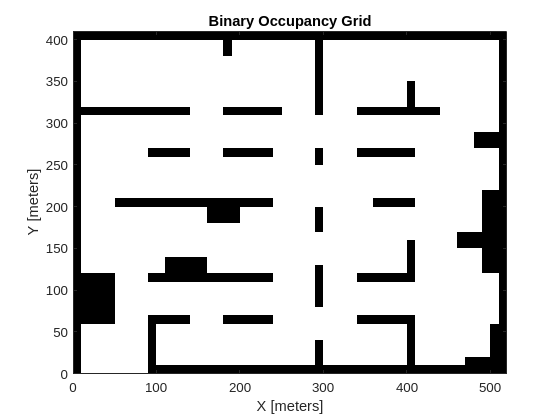

Resolution=.1; % meters
map2 = binaryOccupancyMap(map2,Resolution);
map2 = binaryOccupancyMap(map2);
uavRadius = 2;

Resolution=.1; % meters
map = binaryOccupancyMap(map,Resolution);
map = binaryOccupancyMap(map);


% inflate map
inflate(map2,uavRadius);
show(map)

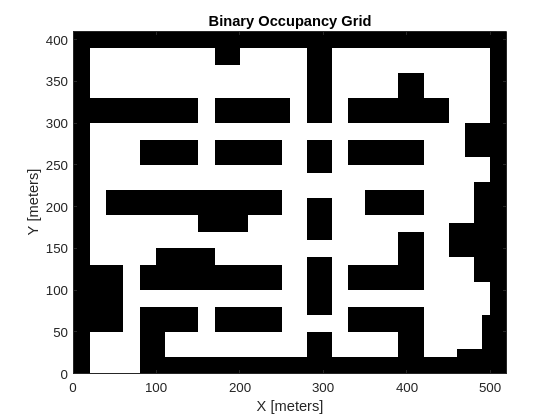

show(map2)

save('bounds_map.mat', 'map')

## Create waypoints

start = [50 25];

p1 = [140 90];
p2 = [125 180];
p3 = [250 40];
p4 = [340 155];
p5 = [315 225];
p6 = [190 360];
p7 = [75 290];
p8 = [140 380];
p9 = [290 290];
p10 = [40 140];
p11 = [320 160];
p12 = [440 50];
p13 = [200 230];
p14 = [435 210];
p15 = [260 275];
p16 = [295 60];
p17 = [370 370];
p18 = [390 240];
p19 = [110 240];
p20 = [260 140];
p21 = [100 350];
p22 = [220 360];
all_waypoints = [p1; p2; p3; p4; p5; p6; p7; p8; p9; p10; p11; p12; p13; p14; p15; p16; p17; p18; p19; p20; p21; p22];
waypoints = all_waypoints;
%waypoints = [p11; p18; p8]
%waypoints = [p19; p6; p9; p11; p20]
waypoints = [p1; p3; p16; p4; p18; p17]

waypoints =    140    90
   250    40
   295    60
   340   155
   390   240
   370   370


## Visualize map and waypoints

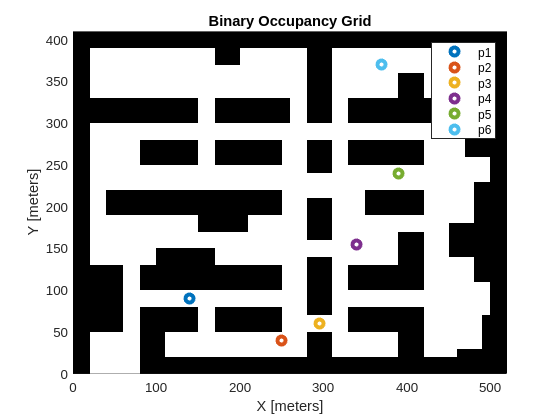

f1 = figure(1); clf;
hold on;
show(map);
%plot(trajectory.start(1), trajectory.start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
for i = 1:length(waypoints(:,1))
%for i = 1:length(trajectory.x_waypoints)
 %   plot(trajectory.x_waypoints(i), trajectory.y_waypoints(i), 'o', 'LineWidth', 3)
   plot(waypoints(i,1), waypoints(i,2), 'o', 'LineWidth', 3, 'DisplayName', sprintf("p%d", i)); 
end
hold off;
legend;

n = length(waypoints);
H = zeros(n,n);
for i=1:n
    for j=1:n
        H(i,j) = pdist([waypoints(i,:); waypoints(j,:)], 'cityblock');
    end
end
save('distance_matrix.mat', 'H')

T = triu(H)

T =      0   105   160   265   310   320   265   290   350   150   250   340   200   415   305   185   510   400   180   170   300   350
     0     0   265   240   235   245   160   215   275   125   215   445   125   340   230   290   435   325    75   175   195   275
     0     0     0   205   250   380   425   450   290   310   190   200   240   355   245    65   450   340   340   110   460   350
     0     0     0     0    95   355   400   425   185   315    25   205   215   150   200   140   245   135   315    95   435   325
     0     0     0     0     0   260   305   330    90   360    70   300   120   135   105   185   200    90   220   140   340   230
     0     0     0     0     0     0   185    70   170   370   330   560   140   395   155   405   190   320   200   290   100    30
     0     0     0     0     0     0     0   155   215   185   375   605   185   440   200   450   375   365    85   335    85   215
     0     0     0     0     0     0     0     0   240   340   40

%plot(trajectory.start(1), trajectory.start(2), 'rx', 'MarkerFaceColor', 'green', 'linewidth', 3);
path_times = [];
path_distances = [];
starts = [];
destinations = [];
x_waypoints = [];
y_waypoints = [];
%
% trajectory_tb = table(path_distance, path_time, start, destination, x_waypoints, y_waypoints)

## Build PRM

save('waypoints.mat', 'waypoints')


22,692.82,11.55,0.01,"{50.0,25.0}","{100.0,350.0}","{290.0,220.0,140.0,100.0}","{290.0,360.0,380.0,350.0}",,,1,1.0,map
23,747.0,12.45,0.01,"{50.0,25.0}","{440.0,50.0}","{40.0,340.0,435.0,440.0}","{140.0,155.0,210.0,50.0}",,,1,1.0,map
24,733.78,12.23,0.01,"{50.0,25.0}","{320.0,160.0}","{125.0,75.0,320.0}","{180.0,290.0,160.0}",,,1,1.0,map
25,768.45,12.81,0.01,"{50.0,25.0}","{100.0,350.0}","{295.0,190.0,100.0}","{60.0,360.0,350.0}",,,1,1.0,map


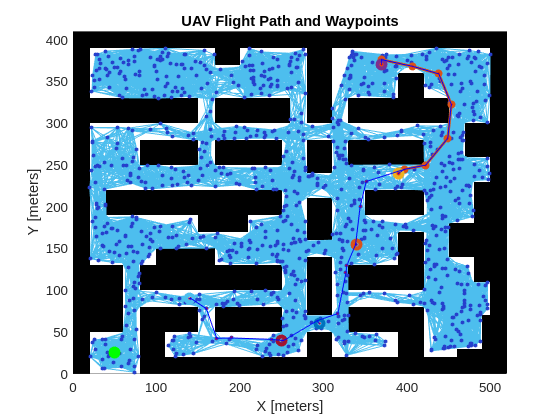

%waypoints = [p1; p2]
prm = mobileRobotPRM;
prm.Map = map;

prm.NumNodes = 1000;
prm.ConnectionDistance = 50;

%path = findpath(prm, start, waypoints(1,:));
path = findpath(prm, waypoints(1,:), waypoints(2,:));
for i = 3:length(waypoints(:,1))
   p = findpath(prm, waypoints(i-1,:), waypoints(i,:));
   path = [path; p];
end
f2 = figure(2); clf;
hold on;
show(prm);
plot(path(:,1), path(:,2), 'r.', 'MarkerSize', 5)
plot(start(1), start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
for i = 1:length(waypoints(:,1))
   plot(waypoints(i,1), waypoints(i,2), 'o', 'LineWidth', 3); 
end
for i = 2:length(path-1)
    plot([path(i-1,1) path(i, 1)], [path(i-1,2) path(i, 2)], 'b');
end
hold off;
title("UAV Flight Path and Waypoints")

## Calculate flight parameters

desiredVelocity = 1; % m/s
path_distance = calculatedistance(path) % total distance to be covered

path_distance = 682.8061

time_interval = calculatetime(path_distance,desiredVelocity); 
stoptimetotal = time_interval(2); % time to complete the mission
% generate smooth time stamped trajectory
sampletimetraj=10; % 0.5 seconds by default
tSamples = sampletimetraj:sampletimetraj:time_interval(2);
[q,qd,qdd,pp] = bsplinepolytraj(path',time_interval,tSamples);
x_ref_points = [tSamples',q(1,:)'];
y_ref_points = [tSamples',q(2,:)'];
path_time = stoptimetotal/60

path_time = 11.3801

## Write trajectory data to db


% the database connection
% conn = database(db_name, username, password);
% %conn = db_connect('nasadb');
% write_trajectory_data(conn, start, path_distance, path_time, waypoints);
% conn.close();
% clear conn;


## Load trajectory data

- Trajectories were loaded to a csv file from the database first

%trajectory_tb = sqlread(conn, 'trajectory_tb');
trajectory_tb = readtable('trajectories/trajectories_jss.csv');

Error using readtable
Unable to find or open 'trajectories/trajectories_jss.csv'. Check the path and filename or file permissions.

max_flight_time = 30.0;

trajectory_tb = trajectory_tb(trajectory_tb.path_time < max_flight_time, :);
trajectory_tb = sortrows(trajectory_tb, "path_time", 'descend')
